# Minimising the Surface Area of an open top Box

The aim is to minimise the surface area of an open top box, given it has a fixed volume $V$.

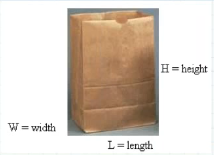

The surface area of this box is shown below (it has no top surface)

syms W L H A V real positive
SA(L,H,W) = W*L+2*W*H+2*H*L

$$SA(L, H, W) = L\,W+2\,H\,L+2\,H\,W$$

The volume enclosed by the box is shown below

eqVol = V==W*L*H

$$eqVol = V=H\,L\,W$$

To minimise the surface area of the box, we need to solve the jacobian $\frac{\partial(SA)}{\partial(L)}, \frac{\partial(SA)}{\partial(W)},\frac{\partial(SA)}{\partial(H)} = 0$. However $H$ is a function of the other two due to the volume equation, as we are using a fixed volume, so we'll substitute that out:

SAcons(W,L) = subs(SA,H,rhs(isolate(eqVol,H)))

$$SAcons(W, L) = L\,W+\frac{2\,V}{L}+\frac{2\,V}{W}$$

eqdSAconsdW = diff(SAcons,W)==0

$$eqdSAconsdW(W, L) = L-\frac{2\,V}{W^{2}}=0$$

eqdSAconsdL = diff(SAcons,L)==0

$$eqdSAconsdL(W, L) = W-\frac{2\,V}{L^{2}}=0$$

Solving the above equations, we get the following relationships

vars = solve({eqVol,eqdSAconsdW,eqdSAconsdL},{L,W,H});
vars.L

$$ans = 2\,{\left(\frac{V}{4}\right)}^{1/3}$$

vars.W

$$ans = 2\,{\left(\frac{V}{4}\right)}^{1/3}$$

vars.H

$$ans = {\left(\frac{V}{4}\right)}^{1/3}$$

vpa(subs(vars.L,V,separateUnits(unitConvert((1.5*u.ft^3),u.in))))

$$ans = 17.306994843688900587859659729361$$

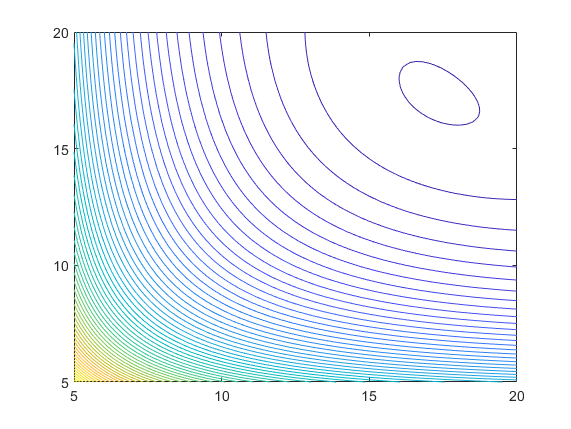

fcontour(subs(SAcons,V,separateUnits(unitConvert((1.5*u.ft^3),u.in))),[5,20,5,20],'LevelStep',20)